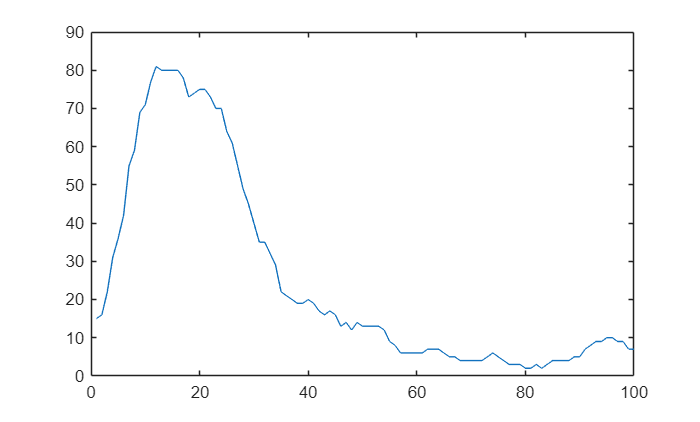

%Main File

%Demo Model
n_population = 200;
pod_size = 4;
T = 100;
infection_rate = 0.4;
recovery_rate = 0.1;
gathering_chance = 0.6;
Iv0 = rand(n_population,1)<0.1;
[~,Ih,Ir] = simulate_absir(n_population,Iv0, T, infection_rate, recovery_rate,pod_size,gathering_chance);
I_count = sum(Ih, 1);
plot(I_count, 'DisplayName', 'Agent-based');